# Height- Weight Regression

Weight increases as height increases.

Independent variable = Height

Dependent Variable = Weight

**1. Get the dataset**

heights = [63 64 66 69 69 71 71 72 73 75];
weights = [127 121 142 157 162 156 169 165 181 208];

**2. Design the table**

T = table(heights',weights','VariableNames',{'heights','weights'});

**3. Fit a Linear Regression Model**

% Default modelspec = linear with last column as response and remaining as predictors
% Weight = Response
% Height = Predictor Variable(s)
% DataType of fit2 = MODEL
model = fitlm(T,'weights~heights')

model = Linear regression model:
    weights ~ 1 + heights

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -266.53      51.032    -5.2229    0.00079977
    heights         6.1376     0.73534     8.3466    3.2138e-05


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 8.64
R-squared: 0.897,  Adjusted R-Squared 0.884
F-statistic vs. constant model: 69.7, p-value = 3.21e-05

**4. Plotting the model**

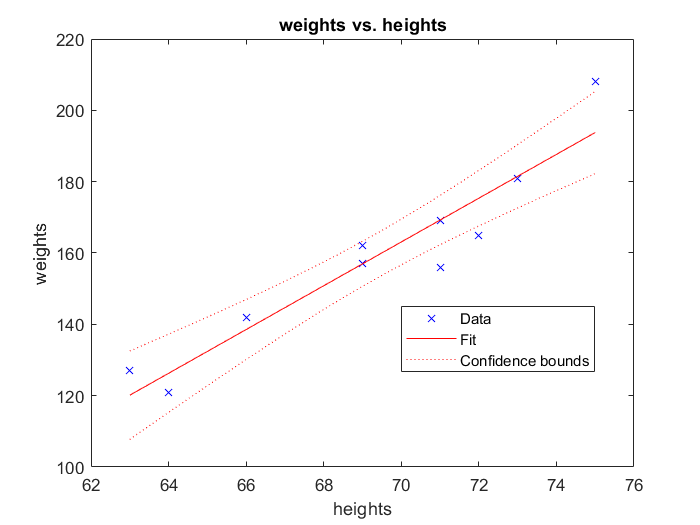

plot(model)

**5. Plotting the Residuals vs Fitted Data**

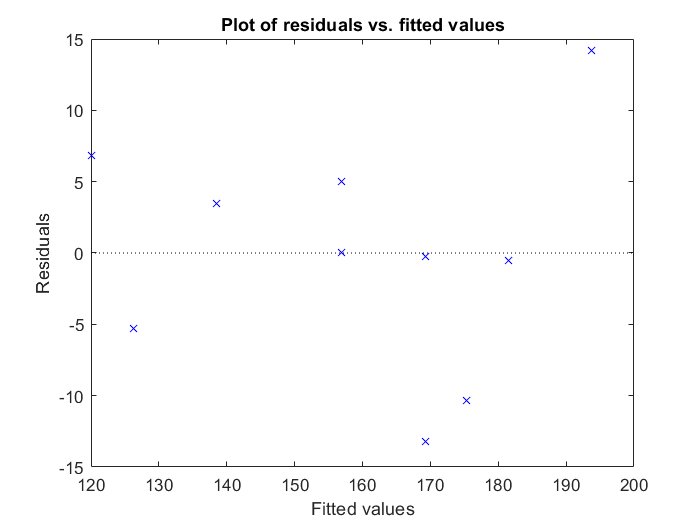

% plotResiduals(MODEL, plottype)
% plottype = fitted
% THIS PLOTS RESIDUALS VS FITTED VALUES
plotResiduals(model,'fitted')

model.plotResiduals('fitted')

**6. Plotting the Cook Distance**

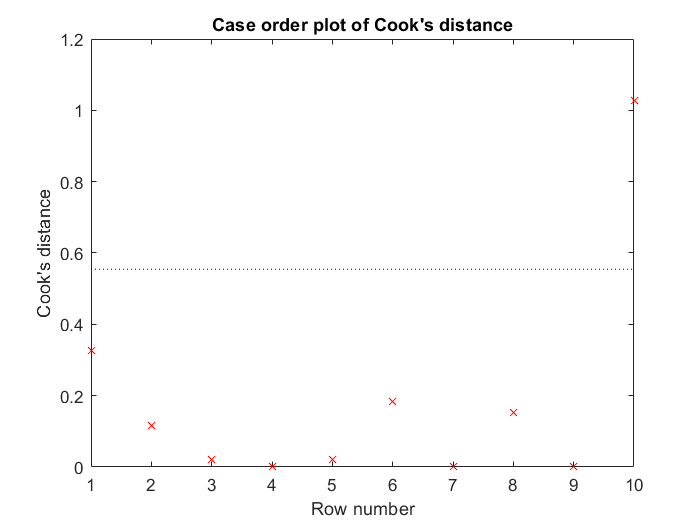

plotDiagnostics(model,'cookd')

model.plotDiagnostics('cookd')

model.plotDiagnostics('')

**7. Removing the outliers**

T(10,:)=[];
model2 = fitlm(T)

model2 = Linear regression model:
    weights ~ 1 + heights

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     -207.5     44.068    -4.7087     0.0021863
    heights         5.2549      0.641     8.1979    7.7954e-05


Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 6.47
R-squared: 0.906,  Adjusted R-Squared 0.892
F-statistic vs. constant model: 67.2, p-value = 7.8e-05

**8. Accessing the properties of the new model**

% Coefficents of Confidence Intervals
disp('CoefCI')

CoefCI


disp(model2.coefCI)

 -311.7086 -103.2979
    3.7392    6.7706



% Cookdistance
disp('Cook Distance')

Cook Distance


disp(model2.Diagnostics.CooksDistance)

    0.1829
    0.5179
    0.0231
    0.0062
    0.0812
    0.2588
    0.0326
    0.1477
    0.1699



% Estimates ( Slope and Intercept)
estimates = model2.Coefficients.Estimate;
c = estimates(1);
m = estimates(2);
disp('Intercept')

Intercept


disp(c)

 -207.5033



disp('Slope')

Slope


disp(m)

    5.2549



**9. Predicting new data**

% using estimates
syms y(x)
y(x) = m*x+c;
vpa(y, 5)

$$ans(x) = 5.2549\,x-207.5$$

vpa(y(75),7)

$$ans = 186.6144$$

vpa(y(0), 7)

$$ans = -207.5033$$

vpa(y(65),7)

$$ans = 134.0654$$

vpa(y(80),7)

$$ans = 212.8889$$


%using predict function
predict(model2,75)

ans = 186.6144

predict(model2,0)

ans = -207.5033

predict(model2,65)

ans = 134.0654

predict(model2,80)

ans = 212.8889


%using models
model2.predict(75)

ans = 186.6144

model2.predict(0)

ans = -207.5033

model2.predict(65)

ans = 134.0654

model2.predict(80)

ans = 212.8889

# Using Least Squares

heights = [63 64 66 69 69 71 71 72 73 75];
weights = [127 121 142 157 162 156 169 165 181 208];
X = [ones(length(heights),1) heights'];
Y = weights';
B = X\Y;
c = B(1)

c = -266.5344

m = B(2)

m = 6.1376

yCalc = X*B;
Rsquare = 1 - sum((Y - yCalc).^2)/sum((Y - mean(Y)).^2)

Rsquare = 0.8970